x = -2:(4/29):2;
y = ((2.*x+1).^2);

alpha = 0.0001;
tau = 0.1;
syms q_sym k_sym;

Nyní si vyjádříme ztrátovou funkcí ve tvatu metody nejmenších čtverců.

E_sym = sum((y - ((x*k_sym + q_sym).^2)).^2);

 A ztrátovou funkci derivujeme. Můžeme buď derivovat jednotlivé členy zvlášť, nebo využít funkce gradient.

grad_E_sym = gradient(E_sym,[q_sym,k_sym]);

Nyní si ještě naplníme první parametr $q$ a $k$ náhodnými hodnotami, v našem případě $q=0,\;k=1$.

q = 0;
k = 1;

V tuhle chvíli mám vše co je potřeba, takže mohu iteračně provádět hledání nových a stále přesnějších parametrů $q$ a $k$, dokud nebude dosažena požadovaná přesnost, nebo dokud nebude dosaženo maximálního počtu iterací. V našem případě jsme zvolili maximální počet iterací $100$.

tic

for i = 1:500 
    dEdq = (double(subs(grad_E_sym(1),[q_sym,k_sym],[q,k])));
    dEdk = (double(subs(grad_E_sym(2),[q_sym,k_sym],[q,k])));
    
    if (abs(dEdq) < tau) && (abs(dEdk) < tau)
        iter = i;
        break;
    end
    q = q - dEdq*alpha;
    k = k - dEdk*alpha;
end

toc

Elapsed time is 1.703837 seconds.


Zkusíme si aproximaci vykreslit do grafu.

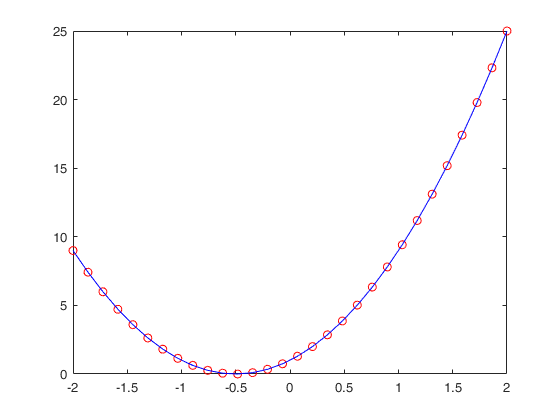

plot(x,y,"ro");
hold on;
plot(x,((k.*x + q).^2),"b-");
hold off;

To by asi taky šlo. Pro zajímavost je možné si vykreslit ještě graf ztrátové funkce, a derivace ztrátové funkce.

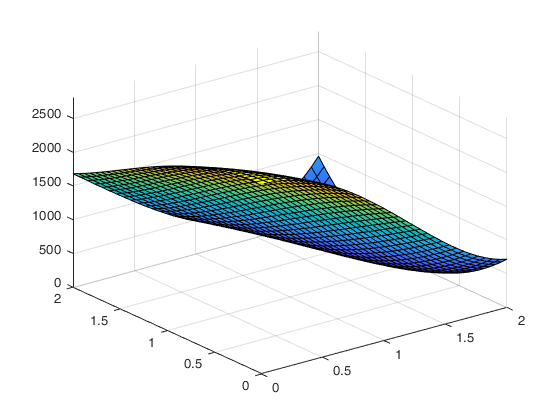

fsurf(E_sym,[0 2 0 2]);
grid on;

Na první pohled je vidět, že se jedná o 3D graf, neboď vyobrazuj ztrátovou funkci v závislosti na dvou parametrech a to $q$ a $k$.

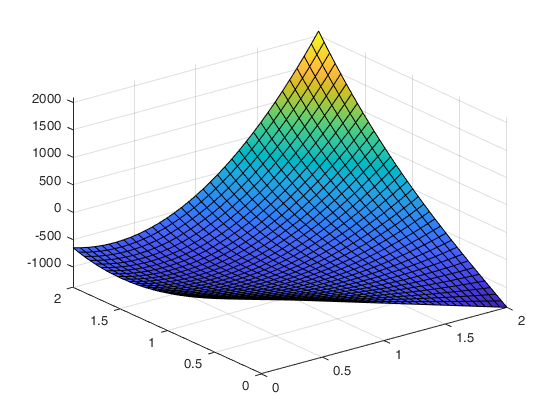

fsurf(grad_E_sym(1),[0 2 0 2]);

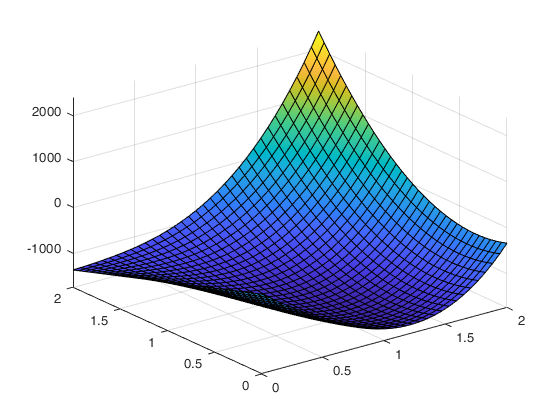

fsurf(grad_E_sym(2),[0 2 0 2]);
grid on;

Při vykreselní gradientu ztrátové funkci musíme vykreslit každou parciální derivaci zvlášť. První odpovídá parciální derivaci ztrátové funcke podle parametru $q$ a druhý zase parciální derivaci ztrátové funkce podle parametru $k$.   